# Distribution Function Calculations

Matlab is able to calculate a wide range of probability distribution functions. Unfortunately, many of these are available only with the add on Statistics Toolbox. However, there is still a lot we can do with just the main Matlab program

##  The Uniform Distribution

Matlab can generate random numbers from a uniform distribution. 

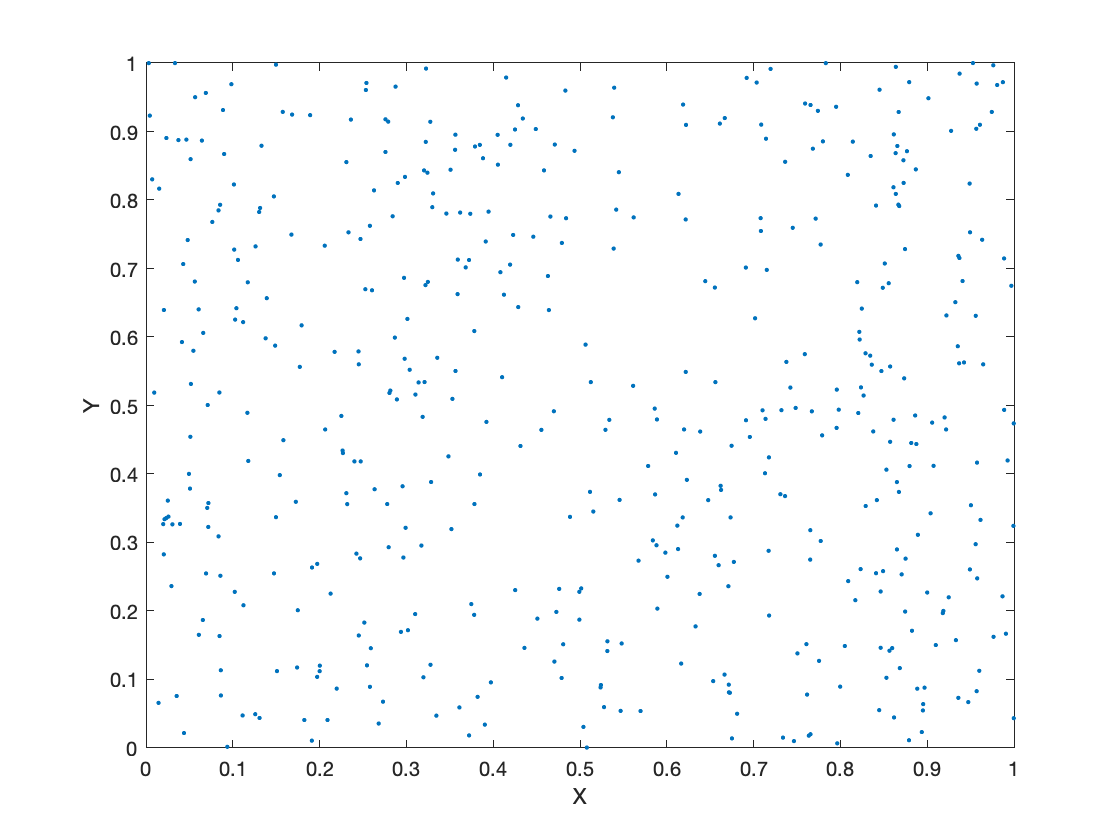

% Specify the number of points we want
n_points = 500;

% Generate two columns of uniformly distributed random numbers that are
% generated from a uniform random distribution between 0 and 1
x_uniform = rand([n_points, 1]); 
y_uniform = rand([n_points, 1]);

figure(1)
plot(x_uniform, y_uniform, '.')
xlabel('X')
ylabel('Y')

We can use the same command to generate random numbers uniformly distributed over a different interval.

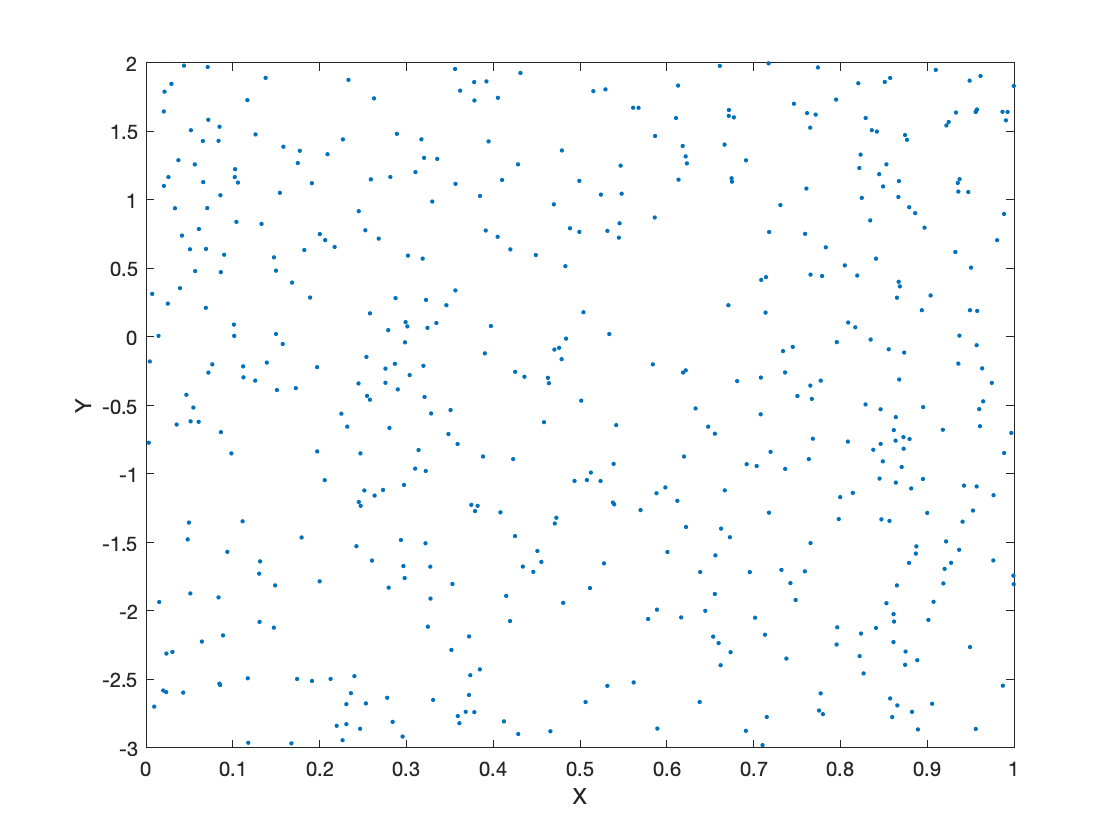

% Generate a column of random numbers uniformly distributed over the
% interval -3 to 2.
y_uniform = -3.0 + 5.0*rand([n_points, 1]); 

figure(2)
plot(x_uniform, y_uniform, '.')
xlabel('X')
ylabel('Y')

Although this looks the similar to the previous plot, notice that the limits on the y-axis are different.

## The Normal Distribution

Matlab can generate random numbers generated from a normal distribution as well. Bu default, the numbers are generated from a normal distribution with a mean of zero and a standard deviation of 1 — i.e. the standardized normal distribution. 

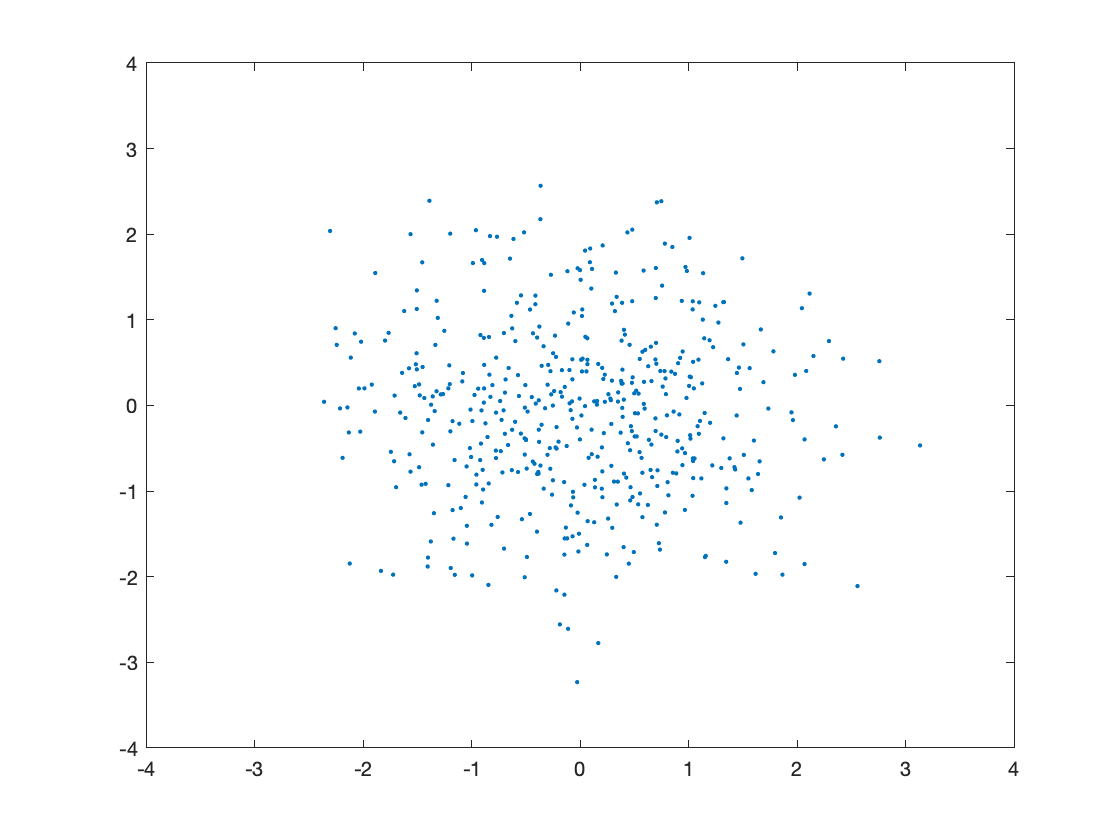

% Generate two columns of normally distributed random numbers
x_normal = randn([n_points, 1]);
y_normal = randn([n_points, 1]);

figure(3)
plot(x_normal, y_normal, '.')
set(gca, 'XLim', [-4,4], 'YLim', [-4,4])

As expected we see that the pattern of points is different from those generated using a uniform distribution; the points are more centrally distributed around the origin. 

We can also use the same command to generate random numbers from a normal distribution that has a non-zero mean and standard deviation different from 1. To do this, we make use of the scaling and translation properties of the normal distribution.

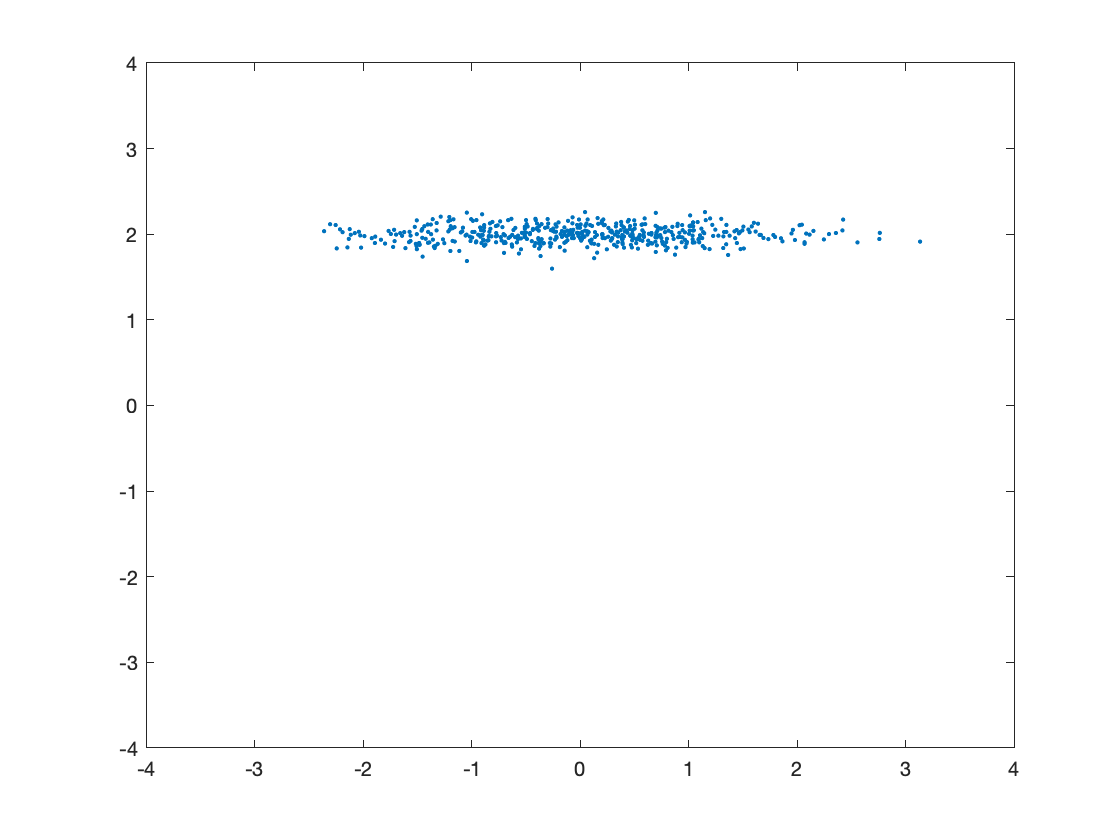

% Generate random numbers from a normal distribution with mean = 2.0 and
% standard deviation = 0.1
y_normal2 = 2.0 + 0.1*randn([n_points,1]);

figure(4)
plot(x_normal, y_normal2, '.')
set(gca, 'XLim', [-4,4], 'YLim', [-4,4])

This plot has been made using the same axis limits as the previous one so that we can see that the difference in standard deviations in the y-direction has resulted in a much narrow distribution in that direction. 

To calculate actual probabilities without the additional Statistics Toolbox requires us to define the normal distribution as a function so that we can calculate the area under the curve using the built-in Matlab numerical integration routines. 

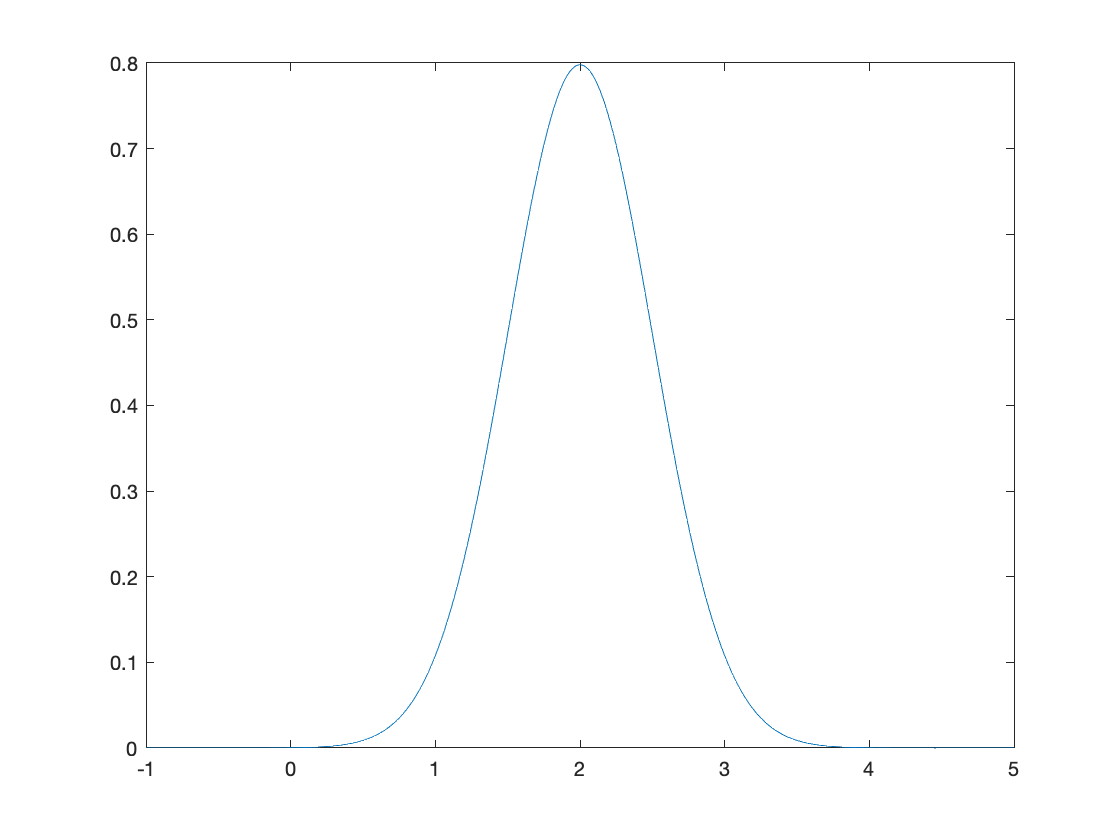

% Define the normal distribution with a mean = m and a standard deviation =
% s.
pr = @(x, m, s) exp(-((x-m).^2)/(2*s.^2)) / (s*sqrt(2*pi));

% Give values to the mean and standard deviation
mean_value = 2.0;
std_dev    = 0.5;

% Specify a range of x-values over which to calculate the distribution.
x = -1.0 : 0.01 : 5.0;

% Calculate and plot the distribution.
y_norm = pr(x, mean_value, std_dev);

figure(5)
plot(x, y_norm)

% Use the built-in Matlab routine to integrate over the normal distribution
% from +\- 1 and 2 standard deviations. 
area_1std = integral(@(x) pr(x, mean_value, std_dev), (mean_value-std_dev), (mean_value+std_dev));
area_2std = integral(@(x) pr(x, mean_value, std_dev), (mean_value-2*std_dev), (mean_value+2*std_dev));

disp(['Area under the curve between +/- 1 standard deviation =' num2str(area_1std)])

Area under the curve between +/- 1 standard deviation =0.68269


disp(['Area under the curve between +/- 2 standard deviation =' num2str(area_2std)])

Area under the curve between +/- 2 standard deviation =0.9545


***Exercise:**** Use Matlab to calculate the probability of obtaining a value between 1 and 2 for a normal distribution with mean of zero and standard deviation of 1.*

***Exercise:**** Calculate the probability of obtaining a value greater than 3 for a normally distribution with a mean of zero and standard deviation of 1.*

***Exercise:**** Cacluate the probability of obtaining a value greater than 3 for a normally distribution with a mean of zero and standard deviation of  2.*

***Exercise:**** Cacluate the probability of obtaining a value greater than 3 for a normally distribution with a mean of 1 and standard deviation of  1.*

***Exercise:**** Cacluate the probability of obtaining a value greater than 3 for a normally distribution with a mean of 1 and standard deviation of  2.*

***Exercise:**** Global warming can increase both the mean temperature of a a region as a well as a range of likely temperatures, or both. How might these changes impact the local temperature in light of your results from the exercises above. *